#                                                             Henrique Silveira Dutra

#                                                                      202110538

#                                      Laboratório de Sistemas de Comunicação Digital I

#                                                                 Experimento 7

## Parte 1   

### TRANSMISSOR

### 1. Inicialmente utilize o modulador/demodulador QPSK desenvolvido nas Experiências 5 e 6 com o filtro RRC. Na entrada do transmissor, gere um bitstream de, no mínimo, 500.000 bits. Assuma que o sinal $u\left(n\right)$ enviado pelo transmissor passa por um canal do tipo AWGN (additive white Gaussian noise), para chegar ao receptor. Para diferentes potências de ruído AWGN, calcule o valor da taxa de erro de bit (BER - bit error rate) através da relação entre a quantidade de bits demodulados com erro e a quantidade total de bits demodulados. Para cada SNR, calcule e armazene o valor da BER. Para gerar o ruído AWGN, utilize a função awgn do Matlab, com a opção ‘measured’.

num_bits = 5e5; % 500.000 bits
bitstream = randi([0, 1], 1, num_bits);

% Chamando a função QPSK_mapper
[I0, Q0] = mapper_QPSK(bitstream);

% Fator de upsample
k = 16;

% Upsampling de I e Q
I0_upsampled = upsample(I0, k);
Q0_upsampled = upsample(Q0, k);

% Parâmetros
SR = 16.6e6; % Symbol Rate
Fc = 32e6; % Frequência da portadora
Fs = SR*k; % Frequência de amostragem
T = 1/SR; 

% Parâmetros do filtro 
alpha = 0.35;     % Fator de roll-off 
span_rrc = 12;    % Duração do filtro em símbolos

% Criando o filtro RRC
rrc = rcosdesign(alpha, span_rrc, k, 'sqrt');

lpf = rrc;

% Aplicação do LPF às sequências I e Q
I0_filtrado = conv(I0_upsampled,lpf);
Q0_filtrado = conv(Q0_upsampled,lpf);

N0 = length(I0_filtrado);
n0 = 0:N0-1;

% Sinal da portadora
carrier_I0 = cos(2*pi*(Fc/Fs)*n0);
carrier_Q0 = sin(2*pi*(Fc/Fs)*n0);

% Heterodinação
u0 = I0_filtrado .* carrier_I0 - Q0_filtrado .* carrier_Q0;

U0 = fft(u0,1024);
U0 = U0(1:(length(U0))/2);

% Frequências normalizadas 
omega0 = linspace(0, pi, length(U0));

% Convertendo para frequências em MHz
f_MHz_U0 = omega0/pi * (Fs/2)/1e6;

### RECEPTOR

% Valores de SNR a serem testados
SNRs = -15:1:6;
BER = zeros(1, length(SNRs));

% Iteração sobre diferentes valores de SNR

for i = 1:length(SNRs)
    SNR = SNRs(i);

    % Adicionar ruído AWGN
    sinal_awgn = awgn(u0, SNR, 'measured');
    
    % Heterodinação no receptor
    Ir = sinal_awgn .* carrier_I0;
    Qr = sinal_awgn .* (-carrier_Q0);

    % Filtragem no receptor
    o = conv(rrc,rrc);
    [~,indice] = max(abs(o));

    I_filtrado_r = conv(Ir,rrc);
    I_filtrado_r = I_filtrado_r(indice:end-indice);

    Q_filtrado_r = conv(Qr,rrc);
    Q_filtrado_r = Q_filtrado_r(indice:end-indice);

    % Downsampling
    I_d = downsample(I_filtrado_r,k);
    Q_d = downsample(Q_filtrado_r,k);

    % Controle de ganho
    m = 0.5; % fator de correção 
    I_d = I_d/m;
    Q_d = Q_d/m;

    % Demapper 
    demapper_qpsk = qpsk_demapper(I_d, Q_d);

    % Cálculo da BER
    erro = sum(xor(bitstream, demapper_qpsk));
    BER(i) = erro/length(bitstream);
    fprintf('SNR: %d dB, BER %e\n' ,SNR, BER(i));
end

SNR: -15 dB, BER 3.073280e-01
SNR: -14 dB, BER 2.864840e-01
SNR: -13 dB, BER 2.623460e-01
SNR: -12 dB, BER 2.393840e-01
SNR: -11 dB, BER 2.127720e-01
SNR: -10 dB, BER 1.852180e-01
SNR: -9 dB, BER 1.568320e-01
SNR: -8 dB, BER 1.302080e-01
SNR: -7 dB, BER 1.034300e-01
SNR: -6 dB, BER 7.885200e-02
SNR: -5 dB, BER 5.557800e-02
SNR: -4 dB, BER 3.716200e-02
SNR: -3 dB, BER 2.265800e-02
SNR: -2 dB, BER 1.231600e-02
SNR: -1 dB, BER 5.878000e-03
SNR: 0 dB, BER 2.348000e-03
SNR: 1 dB, BER 7.660000e-04
SNR: 2 dB, BER 2.120000e-04
SNR: 3 dB, BER 4.800000e-05
SNR: 4 dB, BER 6.000000e-06
SNR: 5 dB, BER 0.000000e+00
SNR: 6 dB, BER 0.000000e+00


### 2. Plote a curva BER versus SNR, juntamente com a curva teórica. Utilize a plotagem semi-logarítmica semilogy.

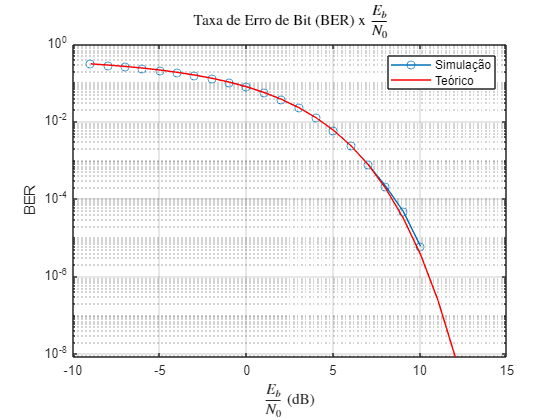

% Cálculo da BER teórica para QPSK
Tsamp = 1/Fs;
Tsym = 1/SR;
EbN0_dB = 10*log10(Tsym/Tsamp) + SNRs - 10*log10(4);
BER_teorica = berawgn(EbN0_dB,'psk', 4, 'nondiff');

% plot da BER x EbN0
figure;
semilogy(EbN0_dB, BER, 'o-', 'DisplayName', 'Simulação');
hold on;
semilogy(EbN0_dB, BER_teorica, 'r-', 'DisplayName', 'Teórico');
hold off;
xlabel('$\frac{E_b}{N_0}$ (dB)','interpreter','latex');
ylabel('BER');
title('Taxa de Erro de Bit (BER) x $\frac{E_b}{N_0}$','Interpreter','Latex');
legend;
grid on;

Como pode ser visto no plot acima, as curvas simulada e teórica estão sobrepostas. Logo, é possível concluir que o desempenho do sistema utilizando a modulação QPSK é satisfatório. 

### 3. Plote e observe o espectro do sinal modulado na saída do canal para valores de SNR alto, médio e baixo. Compare com o espectro do sinal na entrada do canal. Analise os resultados. 

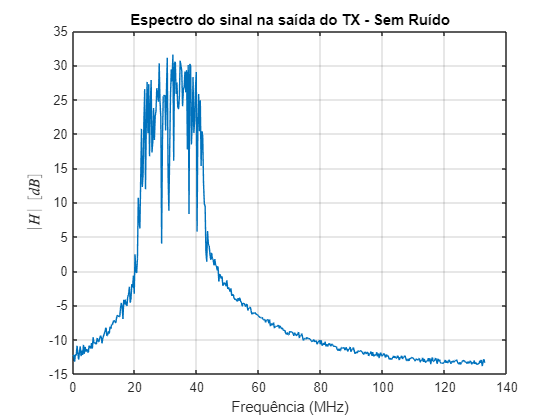

figure;
plot(f_MHz_U0, 20*log10(abs(U0)));
xlabel('Frequência (MHz)');
ylabel('$|H| \ [dB]$', 'Interpreter', 'latex');
title('Espectro do sinal na saída do TX - Sem Ruído');
grid on;

O gráfico acima representa o espectro do sinal a ser transmitido através do canal. Como pode ser visto, ele não apresenta nenhum ruído adicional, o ruído gaussiano será adicionado ao ser transmitido pelo canal.

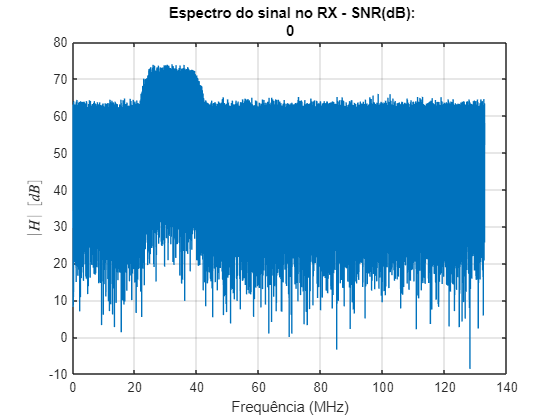

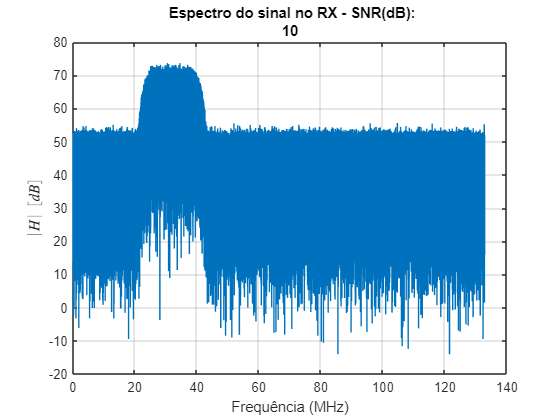

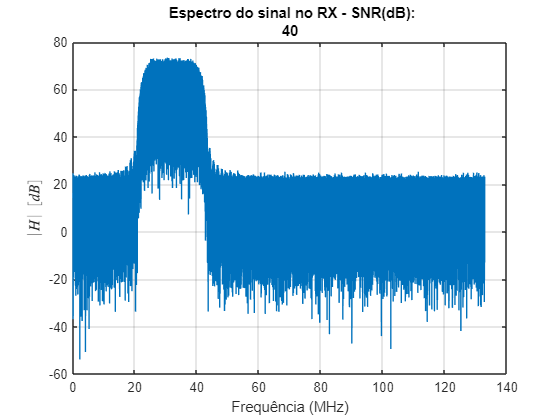

% Valores de SNR a serem testados
SNR_valores = [0 10 40];

for n = 1:length(SNR_valores)
    U = awgn(u0,SNR_valores(n),'measured');

    % FFT que sai do canal AWGN
    fft_u0 = fft(U);
    fft_u0 = fft_u0(1:length(fft_u0)/2);

    freq_fft_u0 = linspace(0, pi, length(fft_u0));
    freq_fft_u0 = (freq_fft_u0/pi)*(Fs/2)/1e6;

    figure;
    plot(freq_fft_u0, 20*log10(abs(fft_u0)));
    xlabel('Frequência (MHz)');
    ylabel('$|H| \ [dB]$', 'Interpreter', 'latex');
    title([" Espectro do sinal no RX - SNR(dB):", SNR_valores(n)]);
    grid on;
end

O ruído branco gaussiano é assim chamado porque a sua potência é uniforme em todo o espectro de frequências. Isso significa que não há preferência por nenhuma frequência específica, o que o torna um tipo de ruído que se estende por todo o espectro. Por isso, ao analisar os plots, o ruído além de estar presente nas extremidades do espectro está também na banda passante do sinal. Além disso, ao aumentar a SNR, maior é a potência do sinal em relação ao ruído, isso implica que há menos interferência do ruído e melhor qualidade do sinal. Quanto mais aumentarmos a SNR, melhor é a fidelidade ao sinal original. Comparando o sinal com SNR alta no receptor com o sinal transmitido, mesmo apresentando ruído, a banda passante que é de interesse apresenta o formato similar.

### 4. Plote e observe a constelação na entrada do de-mapper para diferentes valores de SNR (alto, médio e baixo). Analise os resultados. 

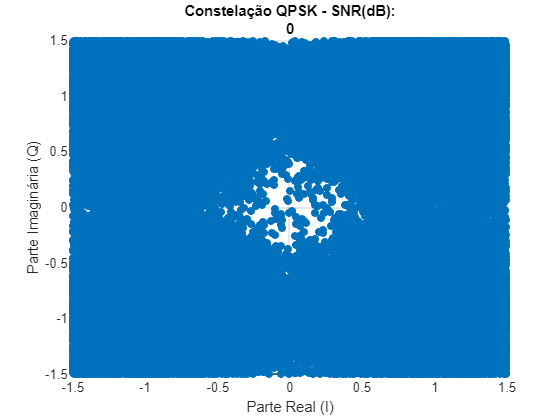

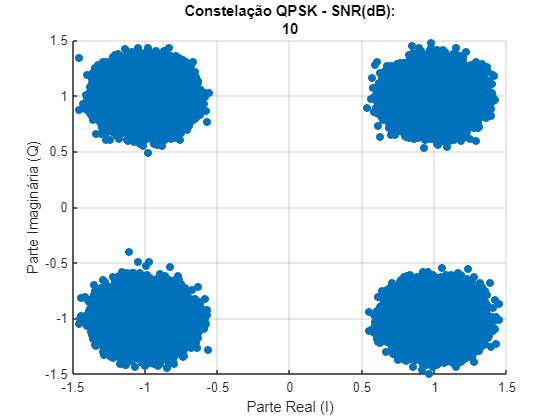

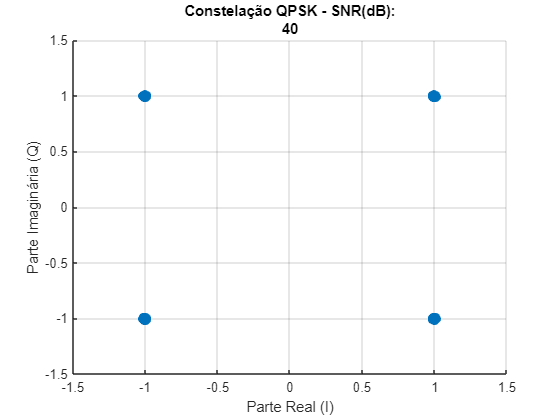

for n = 1:length(SNR_valores)
    U = awgn(u0,SNR_valores(n),'measured');

    % heterodinação 
    Ir = U .* carrier_I0;
    Qr = U .* (-carrier_Q0);
    
    % Processo de filtragem
    o = conv(rrc,rrc);
    [~,indice] = max(abs(o));

    I_filtrado_r = conv(Ir,rrc);
    I_filtrado_r = I_filtrado_r(indice:end-indice);

    Q_filtrado_r = conv(Qr,rrc);
    Q_filtrado_r = Q_filtrado_r(indice:end-indice);

    % Downsampling
    I_d = downsample(I_filtrado_r,k);
    Q_d = downsample(Q_filtrado_r,k);

    % Ajuste de Ganho
    m = 0.5; % fator de correção 
    I_d = I_d/m;
    Q_d = Q_d/m;

    % Constelação obtida para cada SNR
    figure;
    scatter(I_d, Q_d, 'filled');
    xlabel('Parte Real (I)');
    ylabel("Parte Imaginária (Q)");
    title(["Constelação QPSK - SNR(dB):", SNR_valores(n)]);
    grid on;
    axis([-1.5 1.5 -1.5 1.5]);
end

Como pode ser visto nos plots, com a SNR baixa os pontos da constelação se tornam difusos e se sobrepõem, resultando em uma maior probabilidade de erro de detecção de símbolo. Numa SNR média a constelação começa a se definir melhor mas ainda há dispersão dos pontos devido ao ruído. Numa SNR alta a pontência do ruído é muito menor em comparação com a potência do sinal, assim os pontos da constelação estão bem definidos e claramente separados.

### 5. Repita os itens anteriores utilizando o modulador/demodulador 16-QAM desenvolvido nas Experiências 5 e 6. 

## TRANSMISSOR

[I16, Q16] = qam16_mapper(bitstream);

% Upsampling de I e Q
I16_upsampled = upsample(I16, k);
Q16_upsampled = upsample(Q16, k);

% Aplicação do LPF às sequências I e Q
I16_filtrado = conv(I16_upsampled,lpf);
Q16_filtrado = conv(Q16_upsampled,lpf);

N1 = length(I16_filtrado);
n1 = 0:N1-1;

% Sinal da portadora
carrier_I16 = cos(2*pi*(Fc/Fs)*n1);
carrier_Q16 = sin(2*pi*(Fc/Fs)*n1);

% Heterodinação
u16 = I16_filtrado .* carrier_I16 - Q16_filtrado .* carrier_Q16;

U16 = fft(u16,1024);
U16 = U16(1:(length(U16))/2);

% Frequências normalizadas 
omega16 = linspace(0, pi, length(U16));

% Convertendo para frequências em MHz
f_MHz_U16 = omega16/pi * (Fs/2)/1e6;

## RECEPTOR

% Iteração sobre diferentes valores de SNR
SNRs16 = -20:1:10;
BER16 = zeros(1,length(SNRs16));

for q = 1:length(SNRs16)
    SNR16 = SNRs16(q);

    % Adicionar ruído AWGN
    sinal_awgn16 = awgn(u16, SNR16, 'measured');
    
    % Heterodinação no receptor
    Ir16 = sinal_awgn16 .* carrier_I16;
    Qr16 = sinal_awgn16 .* (-carrier_Q16);

    % Filtragem no receptor

    I_filtrado_r16 = conv(Ir16,rrc);
    I_filtrado_r16 = I_filtrado_r16(indice:end-indice);

    Q_filtrado_r16 = conv(Qr16,rrc);
    Q_filtrado_r16 = Q_filtrado_r16(indice:end-indice);

    % Downsampling
    I_d16 = downsample(I_filtrado_r16,k);
    Q_d16 = downsample(Q_filtrado_r16,k);

    % Controle de ganho
    I_d16 = I_d16/m;
    Q_d16 = Q_d16/m;

    % Demapper 
    demapper_16qam = qam16_demapper(I_d16, Q_d16);

    % Cálculo da BER
    erro16 = sum(xor(bitstream, demapper_16qam));
    BER16(q) = erro16/length(bitstream);
    fprintf('SNR: %d dB, BER %e\n' ,SNR16, BER16(q));
end

SNR: -20 dB, BER 4.479160e-01
SNR: -19 dB, BER 4.418940e-01
SNR: -18 dB, BER 4.321620e-01
SNR: -17 dB, BER 4.242320e-01
SNR: -16 dB, BER 4.131520e-01
SNR: -15 dB, BER 4.010020e-01
SNR: -14 dB, BER 3.857440e-01
SNR: -13 dB, BER 3.724640e-01
SNR: -12 dB, BER 3.518000e-01
SNR: -11 dB, BER 3.317460e-01
SNR: -10 dB, BER 3.100480e-01
SNR: -9 dB, BER 2.867060e-01
SNR: -8 dB, BER 2.611000e-01
SNR: -7 dB, BER 2.375220e-01
SNR: -6 dB, BER 2.120080e-01
SNR: -5 dB, BER 1.877460e-01
SNR: -4 dB, BER 1.632900e-01
SNR: -3 dB, BER 1.408200e-01
SNR: -2 dB, BER 1.192260e-01
SNR: -1 dB, BER 9.722800e-02
SNR: 0 dB, BER 7.685600e-02
SNR: 1 dB, BER 5.836200e-02
SNR: 2 dB, BER 4.169200e-02
SNR: 3 dB, BER 2.744000e-02
SNR: 4 dB, BER 1.685600e-02
SNR: 5 dB, BER 9.244000e-03
SNR: 6 dB, BER 4.284000e-03
SNR: 7 dB, BER 1.758000e-03
SNR: 8 dB, BER 5.620000e-04
SNR: 9 dB, BER 1.380000e-04
SNR: 10 dB, BER 3.200000e-05


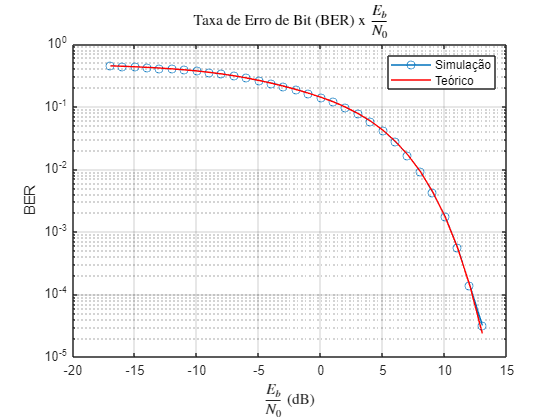

% Cálculo da BER teórica para QPSK
EbN0_dB16 = 10*log10(Tsym/Tsamp) + SNRs16 - 10*log10(8);
BER_teorica16 = berawgn(EbN0_dB16,"qam", 16);

% plot da BER x EbN0
figure;
semilogy(EbN0_dB16, BER16, 'o-', 'DisplayName', 'Simulação');
hold on;
semilogy(EbN0_dB16, BER_teorica16, 'r-', 'DisplayName', 'Teórico');
hold off;
xlabel('$\frac{E_b}{N_0}$ (dB)','interpreter','latex');
ylabel('BER');
title('Taxa de Erro de Bit (BER) x $\frac{E_b}{N_0}$','Interpreter','Latex');
legend;
grid on;

Como pode ser visto no plot acima, as curvas simulada e teórica estão sobrepostas. Logo, é possível concluir que o desempenho do sistema utilizando a modulação 16-QAM é satisfatório.

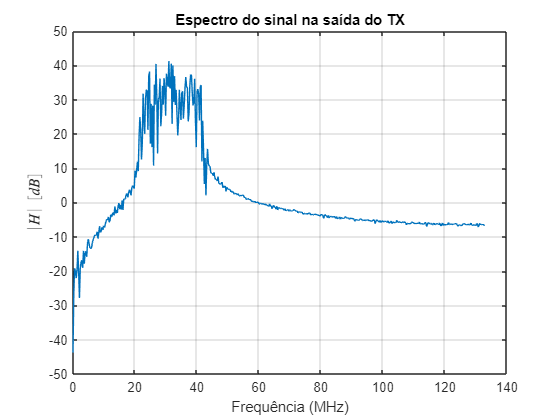

figure;
plot(f_MHz_U16, 20*log10(abs(U16)));
xlabel('Frequência (MHz)');
ylabel('$|H| \ [dB]$', 'Interpreter', 'latex');
title('Espectro do sinal na saída do TX');
grid on;

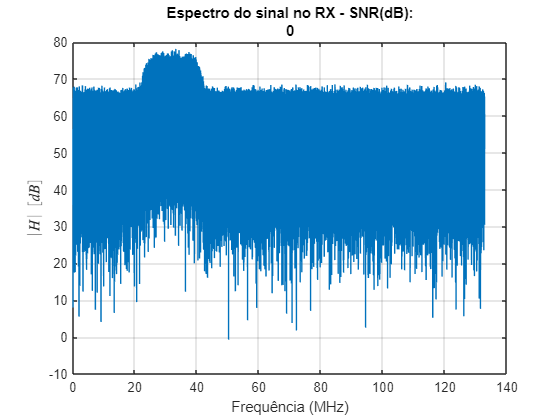

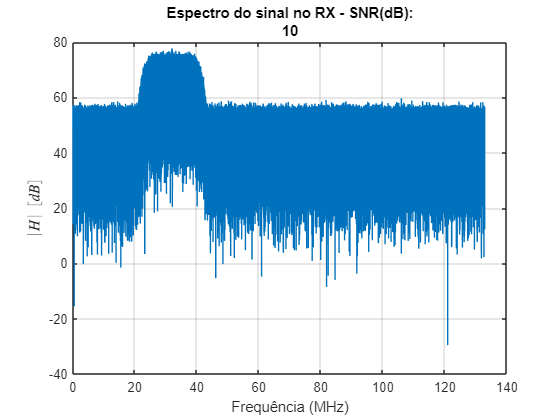

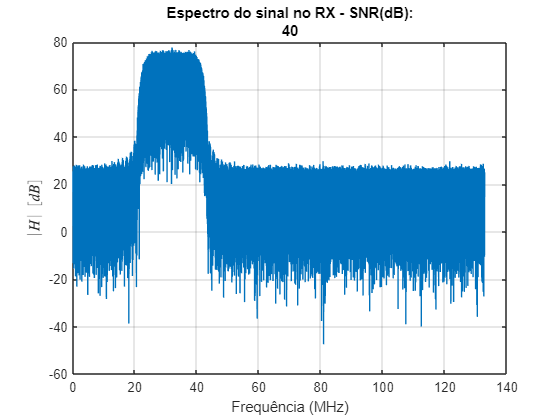

for z = 1:length(SNR_valores)
    U = awgn(u16,SNR_valores(z),'measured');

    % FFT que sai do canal AWGN
    fft_u16 = fft(U);
    fft_u16 = fft_u16(1:length(fft_u16)/2);

    freq_fft_u16 = linspace(0, pi, length(fft_u16));
    freq_fft_u16 = (freq_fft_u16/pi)*(Fs/2)/1e6;

    figure;
    plot(freq_fft_u16, 20*log10(abs(fft_u16)));
    xlabel('Frequência (MHz)');
    ylabel('$|H| \ [dB]$', 'Interpreter', 'latex');
    title(["Espectro do sinal no RX - SNR(dB):", SNR_valores(z)]);
    grid on;
end

O ruído branco gaussiano é assim chamado porque a sua potência é uniforme em todo o espectro de frequências. Isso significa que não há preferência por nenhuma frequência específica, o que o torna um tipo de ruído que se estende por todo o espectro. Por isso, ao analisar os plots, o ruído além de estar presente nas extremidades do espectro está também na banda passante do sinal. Além disso, ao aumentar a SNR, maior é a potência do sinal em relação ao ruído, isso implica que há menos interferência do ruído e melhor qualidade do sinal. Quanto mais aumentarmos a SNR, melhor é a fidelidade ao sinal original. Comparando o sinal com SNR alta no receptor com o sinal transmitido, mesmo apresentando ruído, a banda passante que é de interesse apresenta o formato similar.

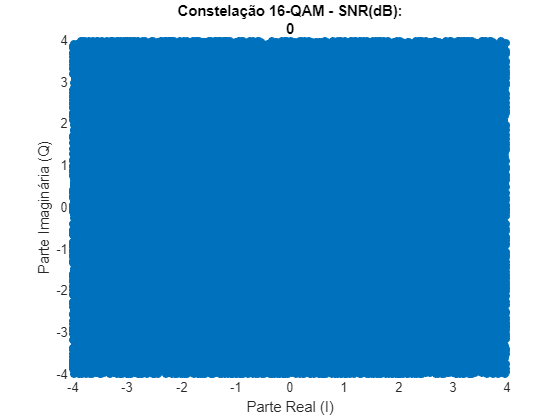

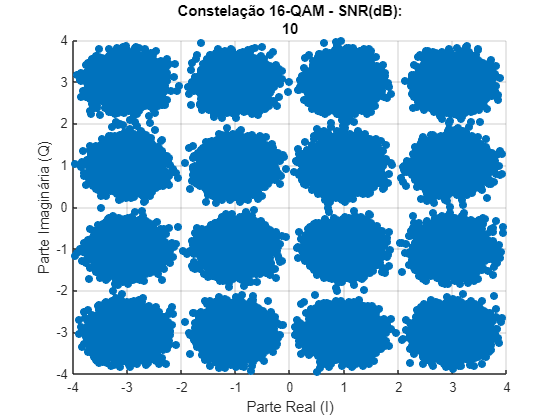

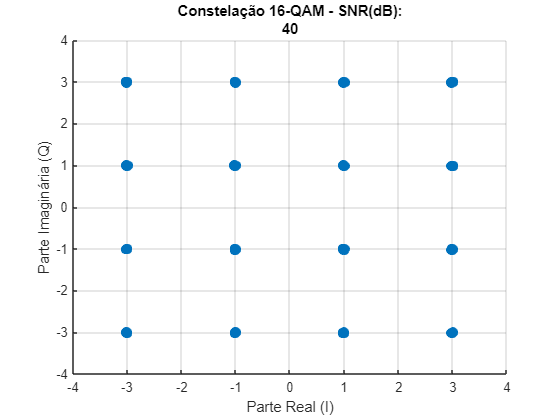

for y = 1:length(SNR_valores)
    U = awgn(u16,SNR_valores(y),'measured');

    % heterodinação 
    Ir = U .* carrier_I16;
    Qr = U .* (-carrier_Q16);
    
    % Processo de filtragem
    o = conv(rrc,rrc);
    [~,indice] = max(abs(o));

    I_filtrado_r = conv(Ir,rrc);
    I_filtrado_r = I_filtrado_r(indice:end-indice);

    Q_filtrado_r = conv(Qr,rrc);
    Q_filtrado_r = Q_filtrado_r(indice:end-indice);

    % Downsampling
    I_d = downsample(I_filtrado_r,k);
    Q_d = downsample(Q_filtrado_r,k);

    % Ajuste de Ganho
    m = 0.5; % fator de correção 
    I_d = I_d/m;
    Q_d = Q_d/m;

    % Constelação obtida para cada SNR
    figure;
    scatter(I_d, Q_d, 'filled');
    xlabel('Parte Real (I)');
    ylabel("Parte Imaginária (Q)");
    title(["Constelação 16-QAM - SNR(dB):", SNR_valores(y)]);
    grid on;
    axis([-4 4 -4 4]);
end

Como pode ser visto nos plots, com a SNR baixa os pontos da constelação se tornam difusos e se sobrepõem, resultando em uma maior probabilidade de erro de detecção de símbolo. Numa SNR média a constelação começa a se definir melhor mas ainda há dispersão dos pontos devido ao ruído. Numa SNR alta a pontência do ruído é muito menor em comparação com a potência do sinal, assim os pontos da constelação estão bem definidos e claramente separados.

### 6. Ao final das simulações, plote em um único gráfico as curvas BER versus $\frac{E_b }{N_0 }$ (ou SNR) para as modulações QPSK e 16-QAM, utilizando plotagem semi-logarítmica semilogy do Matlab. Analise os resultados.

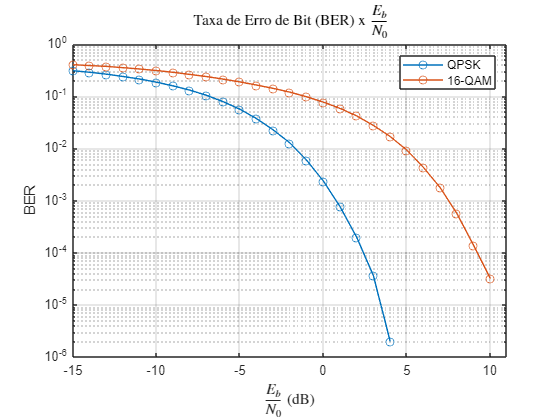

% Valores de SNR a serem testados
figure;
semilogy(SNRs, BER, 'o-','DisplayName','QPSK');
hold on;
semilogy(SNRs16, BER16, 'o-','DisplayName','16-QAM');
hold off;
xlabel('$\frac{E_b}{N_0}$ (dB)','interpreter','latex');
ylabel('BER');
title('Taxa de Erro de Bit (BER) x $\frac{E_b}{N_0}$','Interpreter','Latex');
legend('show');
axis([-15 11 1e-6 1]);
grid on;

Como pode ser visto, para uma mesma SNR a modulação QPSK apresenta uma BER menor que a modulação 16-QAM. Esse fato ocorre porque a modulação 16-QAM é mais sensível ao ruído em comparação com a modulação QPSK, visto que apresenta mais símbolos e por consequência mais regiões de decisão. Logo, é mais fácil de ocorrer erro de símbolo na modulação 16-QAM do que na QPSK.

## PARTE 2

### 1. Utilize o codificador de canal desenvolvido na Experiência 4 e o modulador/demodulador QPSK desenvolvido nas Experiências 5 e 6. Na entrada do transmissor, gere um bitstream de, no mínimo, 500.000 bits e codifique a sequência utilizando o codificador de canal. Aplique a saída do codificador de canal a entrada do modulador. Assuma que o sinal $u\left(n\right)$ correspondente a saída do transmissor passa por um canal do tipo AWGN, para chegar ao receptor. No receptor, o sinal é demodulado e a sequência de bits é enviada ao decodificador de canal. Para diferentes potências de ruído AWGN, calcule o valor da BER através da relação entre a quantidade de bits decodificados com erro e a quantidade total de bits decodificados. Para cada SNR, calcule e armazene o valor da BER.

G =  [1 0 1 1 0;
      0 1 1 0 1];% matriz geradora

palavra_codigo = codificador(G, bitstream); 

H = [1 1 1 0 0;
    1 0 0 1 0 ;
    0 1 0 0 1 ]; % matriz de paridade

sindrome_erro_tabela = [ ...
        0 0 0   0 0 0 0 0; ...
        0 0 1   0 0 0 0 1; ...
        0 1 0   0 0 0 1 0; ...
        0 1 1   0 0 0 1 1; ...                          
        1 0 0   0 0 1 0 0; ...
        1 0 1   0 1 0 0 0; ...                          
        1 1 0   1 0 0 0 0; ...                          
        1 1 1   1 0 0 0 1  ...                          
    ]; % tabela de síndromes associadas ao padrão de erro

% Chamando a função QPSK_mapper
[Ic, Qc] = mapper_QPSK(palavra_codigo);

% Upsampling de I e Q
Ic_upsampled = upsample(Ic, k);
Qc_upsampled = upsample(Qc, k);

% Aplicação do LPF às sequências I e Q
Ic_filtrado = conv(Ic_upsampled,lpf);
Qc_filtrado = conv(Qc_upsampled,lpf);

Nc = length(Ic_filtrado);
nc = 0:Nc-1;

% Sinal da portadora
carrier_Ic = cos(2*pi*(Fc/Fs)*nc);
carrier_Qc = sin(2*pi*(Fc/Fs)*nc);

% Heterodinação
uc = Ic_filtrado .* carrier_Ic - Qc_filtrado .* carrier_Qc;

Uc = fft(uc,1024);
Uc = Uc(1:(length(Uc))/2);

% Frequências normalizadas 
omegac = linspace(0, pi, length(Uc));

% Convertendo para frequências em MHz
f_MHz_Uc = omegac/pi * (Fs/2)/1e6;

## RECEPTOR

% Valores de SNR a serem testados
SNRsc = -15:1:6;
BERc = zeros(1, length(SNRsc));

% Iteração sobre diferentes valores de SNR

for i = 1:length(SNRsc)
    SNRc = SNRsc(i);

    % Adicionar ruído AWGN
    sinal_awgnc = awgn(uc, SNRc, 'measured');
    
    % Heterodinação no receptor
    Irc = sinal_awgnc .* carrier_Ic;
    Qrc = sinal_awgnc .* (-carrier_Qc);

    % Filtragem no receptor
    oc = conv(rrc,rrc);
    [~,indicec] = max(abs(oc));

    I_filtrado_rc = conv(Irc,rrc);
    I_filtrado_rc = I_filtrado_rc(indicec:end-indicec);

    Q_filtrado_rc = conv(Qrc,rrc);
    Q_filtrado_rc = Q_filtrado_rc(indicec:end-indicec);

    % Downsampling
    I_dc = downsample(I_filtrado_rc,k);
    Q_dc = downsample(Q_filtrado_rc,k);

    % Controle de ganho
    mc = 0.5; % fator de correção 
    I_dc = I_dc/mc;
    Q_dc = Q_dc/mc;

    % Demapper 
    demapper_qpskc = qpsk_demapper(I_dc, Q_dc);

    % Decodificador
    [mensagens, sindromes, codewords_correto] = decod_codigo_bloco(H, sindrome_erro_tabela, demapper_qpskc);

    % Cálculo da BER
    erroc = sum(xor(palavra_codigo, codewords_correto));
    BERc(i) = erroc/length(palavra_codigo);
    fprintf('SNR: %d dB, BER %e\n' ,SNRc, BERc(i));
end

SNR: -15 dB, BER 2.802440e-01
SNR: -14 dB, BER 2.528440e-01
SNR: -13 dB, BER 2.236944e-01
SNR: -12 dB, BER 1.939688e-01
SNR: -11 dB, BER 1.619136e-01
SNR: -10 dB, BER 1.289288e-01
SNR: -9 dB, BER 9.802320e-02
SNR: -8 dB, BER 6.936240e-02
SNR: -7 dB, BER 4.641280e-02
SNR: -6 dB, BER 2.794400e-02
SNR: -5 dB, BER 1.515280e-02
SNR: -4 dB, BER 6.587200e-03
SNR: -3 dB, BER 2.521600e-03
SNR: -2 dB, BER 8.096000e-04
SNR: -1 dB, BER 1.776000e-04
SNR: 0 dB, BER 3.200000e-05
SNR: 1 dB, BER 5.600000e-06
SNR: 2 dB, BER 0.000000e+00
SNR: 3 dB, BER 0.000000e+00
SNR: 4 dB, BER 0.000000e+00
SNR: 5 dB, BER 0.000000e+00
SNR: 6 dB, BER 0.000000e+00


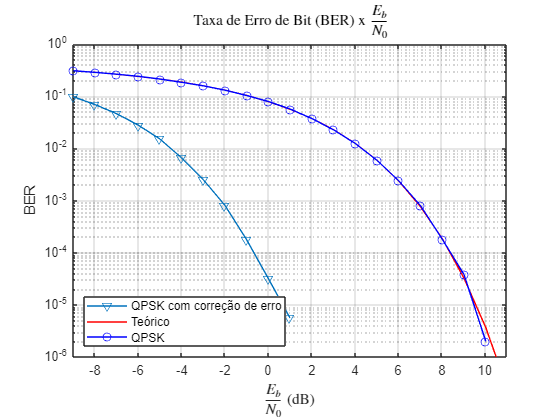

% Plot da BER x SNR
figure;
semilogy(SNRsc, BERc, 'v-', 'DisplayName', 'QPSK com correção de erro');
hold on
semilogy(EbN0_dB, BER_teorica, 'r-', 'DisplayName', 'Teórico');
semilogy(EbN0_dB, BER, 'bo-','DisplayName', 'QPSK');
xlabel('$\frac{E_b}{N_0}$ (dB)','interpreter','latex');
ylabel('BER');
title('Taxa de Erro de Bit (BER) x $\frac{E_b}{N_0}$','Interpreter','Latex');
grid on;
legend('show', 'Location', 'Southwest');
axis([-9 11 1e-6 1]);

Como pode ser visto acima, utilizando os blocos codificador e decodificador reduziu drasticamente a BER para uma mesma SNR. Logo, mesmo com a inserção de ruído gaussiano, o código detector de erro conseguiu corrigir os bits errados das palavras códigos recebidas que possuiam padrões de erro de peso 1 e dois possíveis padrões de erro de peso 2, melhorando significativamente o desempenho do sistema. Para demais padrões de erro de peso 2 ou pesos maiores, ocorre erro e por consequência ocorre BER para determinada SNR. Como foi utilizada a matriz geradora do experimento 4, as síndromes relacionadas aos padrões de erro estão listadas abaixo:

                        
$$\begin{array}{ll}
\text{Síndrome}\ s_i & \text{Padrão de Erro}\ e_i \\
[0\ 0\ 0] & [0\ 0\ 0\ 0\ 0] \\
[0\ 0\ 1] & [0\ 0\ 0\ 0\ 1] \\
[0\ 1\ 0] & [0\ 0\ 0\ 1\ 0] \\
[0\ 1\ 1] & [0\ 0\ 0\ 1\ 1] \\
[1\ 0\ 0] & [0\ 0\ 1\ 0\ 0] \\
[1\ 0\ 1] & [0\ 1\ 0\ 0\ 0] \\
[1\ 1\ 0] & [1\ 0\ 0\ 0\ 0] \\
[1\ 1\ 1] & [1\ 0\ 0\ 0\ 1] \\
\end{array}$$


### 2. Repita o item 1 utilizando o modulador/demodulador 16-QAM desenvolvido nas Experiências 5 e 6.

## TRANSMISSOR

% Chamando a função QPSK_mapper
[Ic16, Qc16] = qam16_mapper(palavra_codigo);

% Upsampling de I e Q
Ic16_upsampled = upsample(Ic16, k);
Qc16_upsampled = upsample(Qc16, k);

% Aplicação do LPF às sequências I e Q
Ic16_filtrado = conv(Ic16_upsampled,lpf);
Qc16_filtrado = conv(Qc16_upsampled,lpf);

Nc16 = length(Ic16_filtrado);
nc16 = 0:Nc16-1;

% Sinal da portadora
carrier_Ic16 = cos(2*pi*(Fc/Fs)*nc16);
carrier_Qc16 = sin(2*pi*(Fc/Fs)*nc16);

% Heterodinação
uc16 = Ic16_filtrado .* carrier_Ic16 - Qc16_filtrado .* carrier_Qc16;

## RECEPTOR

% Valores de SNR a serem testados
SNRsc16 = -20:1:10;
BERc16 = zeros(1, length(SNRsc16));

% Iteração sobre diferentes valores de SNR

for s = 1:length(SNRsc16)
    SNRc16 = SNRsc16(s);

    % Adicionar ruído AWGN
    sinal_awgnc16 = awgn(uc16, SNRc16, 'measured');
    
    % Heterodinação no receptor
    Irc16 = sinal_awgnc16 .* carrier_Ic16;
    Qrc16 = sinal_awgnc16 .* (-carrier_Qc16);

    % Filtragem no receptor
    oc16 = conv(rrc,rrc);
    [~,indicec16] = max(abs(oc16));

    I_filtrado_rc16 = conv(Irc16,rrc);
    I_filtrado_rc16 = I_filtrado_rc16(indicec16:end-indicec16);

    Q_filtrado_rc16 = conv(Qrc16,rrc);
    Q_filtrado_rc16 = Q_filtrado_rc16(indicec16:end-indicec16);

    % Downsampling
    I_dc16 = downsample(I_filtrado_rc16,k);
    Q_dc16 = downsample(Q_filtrado_rc16,k);

    % Controle de ganho
    mc16 = 0.5; % fator de correção 
    I_dc16 = I_dc16/mc16;
    Q_dc16 = Q_dc16/mc16;

    % Demapper 
    demapper_qamc16 = qam16_demapper(I_dc16, Q_dc16);

    % Decodificador
    [mensagens16, sindromes16, codewords_correto16] = decod_codigo_bloco(H, sindrome_erro_tabela, demapper_qamc16);

    % Cálculo da BER
    erroc16 = sum(xor(palavra_codigo, codewords_correto16));
    BERc16(s) = erroc16/length(palavra_codigo);
    fprintf('SNR: %d dB, BER %e\n' ,SNRc16, BERc16(s));
end

SNR: -20 dB, BER 4.430920e-01
SNR: -19 dB, BER 4.351424e-01
SNR: -18 dB, BER 4.247944e-01
SNR: -17 dB, BER 4.157664e-01
SNR: -16 dB, BER 4.032960e-01
SNR: -15 dB, BER 3.885368e-01
SNR: -14 dB, BER 3.744064e-01
SNR: -13 dB, BER 3.550744e-01
SNR: -12 dB, BER 3.345048e-01
SNR: -11 dB, BER 3.093608e-01
SNR: -10 dB, BER 2.829488e-01
SNR: -9 dB, BER 2.536320e-01
SNR: -8 dB, BER 2.220952e-01
SNR: -7 dB, BER 1.910168e-01
SNR: -6 dB, BER 1.591952e-01
SNR: -5 dB, BER 1.279400e-01
SNR: -4 dB, BER 1.000744e-01
SNR: -3 dB, BER 7.567680e-02
SNR: -2 dB, BER 5.434240e-02
SNR: -1 dB, BER 3.672560e-02
SNR: 0 dB, BER 2.357040e-02
SNR: 1 dB, BER 1.388640e-02
SNR: 2 dB, BER 7.096800e-03
SNR: 3 dB, BER 3.037600e-03
SNR: 4 dB, BER 1.237600e-03
SNR: 5 dB, BER 3.264000e-04
SNR: 6 dB, BER 8.720000e-05
SNR: 7 dB, BER 4.800000e-06
SNR: 8 dB, BER 0.000000e+00
SNR: 9 dB, BER 0.000000e+00
SNR: 10 dB, BER 0.000000e+00


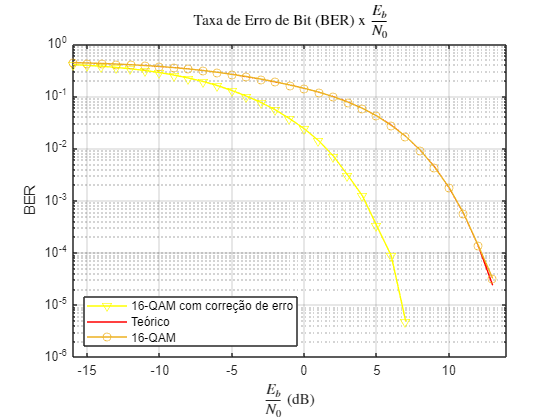

% Plot da BER x SNR
figure;
semilogy(SNRsc16, BERc16, 'yv-', 'DisplayName', '16-QAM com correção de erro');
hold on
semilogy(EbN0_dB16, BER_teorica16, 'r-', 'DisplayName', 'Teórico');
semilogy(EbN0_dB16, BER16, 'o-','DisplayName', '16-QAM');
xlabel('$\frac{E_b}{N_0}$ (dB)','interpreter','latex');
ylabel('BER');
title('Taxa de Erro de Bit (BER) x $\frac{E_b}{N_0}$','Interpreter','Latex');
grid on;
legend('show', 'Location', 'Southwest');
axis([-16 14 1e-6 1]);

Como pode ser visto acima, utilizando os blocos codificador e decodificador reduziu drasticamente a BER para uma mesma SNR. Logo, mesmo com a inserção de ruído gaussiano, o código detector de erro conseguiu corrigir os bits errados das palavras códigos recebidas que possuiam padrões de erro de peso 1 e dois possíveis padrões de erro de peso 2, melhorando significativamente o desempenho do sistema. Para demais padrões de erro de peso 2 ou pesos maiores, ocorre erro e por consequência ocorre BER para determinada SNR.

### 3. Ao final das simulações, plote em um único gráfico, as curvas BER versus SNR para as modulações QPSK e 16-QAM obtidas nas partes I e II (quatro curvas), utilizando plotagem semi-logarítmica semilogy do Matlab. 

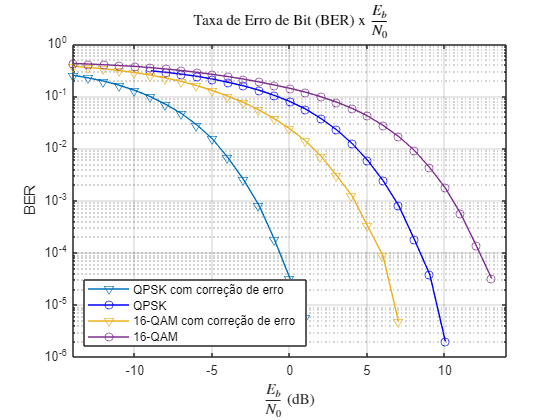

figure;
semilogy(SNRsc, BERc, 'v-', 'DisplayName', 'QPSK com correção de erro');
hold on
semilogy(EbN0_dB, BER, 'bo-','DisplayName', 'QPSK');
semilogy(SNRsc16, BERc16, 'v-', 'DisplayName', '16-QAM com correção de erro');
semilogy(EbN0_dB16, BER16, 'o-','DisplayName', '16-QAM');
xlabel('$\frac{E_b}{N_0}$ (dB)','interpreter','latex');
ylabel('BER');
title('Taxa de Erro de Bit (BER) x $\frac{E_b}{N_0}$','Interpreter','Latex');
grid on;
legend('show', 'Location', 'Southwest');
axis([-14 14 1e-6 1]);

Como dito anteriormente, é evidente que utilizando os blocos codificador e decodificador o desempenho do sistema para cada modulação melhorou significativamente. Ou seja, para a mesma SNR a BER melhorou (reduziu) muito em comparação à transmissão sem correção de erro. Um fato curioso dos resultados é que a modulação 16-QAM com correção de erro para uma mesma SNR apresentou BER menor em comparação à modulação QPSK, mesmo tendo uma modulação mais sensível ao ruído em comparação à QPSK. Isso justifica a importância dos blocos corretores de erro no processo de transmissão e recepção de sinais, com a finalidade de reduzir a BER para SNRs que podem comprometer a transmissão do sinal.